## Очищення середовища

clear, close all

## 1.Завантаження зображень

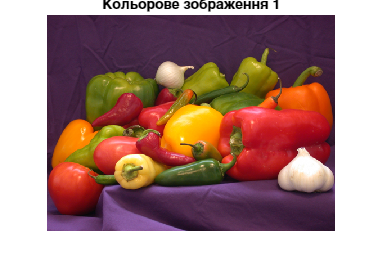

image1 = imread('peppers.png');
image2 = imread('cameraman.tif');

% Виведення на екран
figure, imshow(image1), title('Кольорове зображення 1');

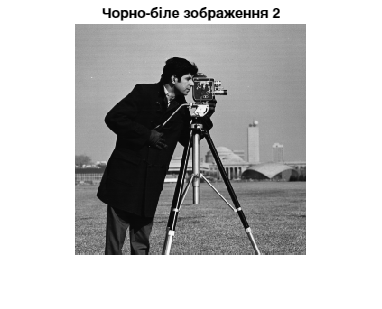

figure, imshow(image2), title('Чорно-біле зображення 2');

## 2.Перетворення кольорових зображень в чорно-білі

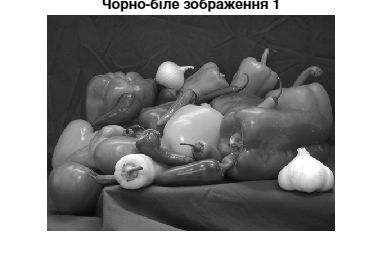

image1_gray = rgb2gray(image1);

% Виведення на екран
figure, imshow(image1_gray), title('Чорно-біле зображення 1');

## 3.Виконання ДКП

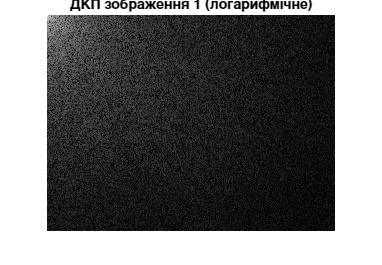

dct_image1 = dct2(image1_gray);
dct_image2 = dct2(image2);

% Логарифмічне масштабування та відображення результату
dct_image1_log = log(abs(dct_image1) + 1);
dct_image2_log = log(abs(dct_image2) + 1);
figure, imshow(dct_image1_log, []), title('ДКП зображення 1 (логарифмічне)');

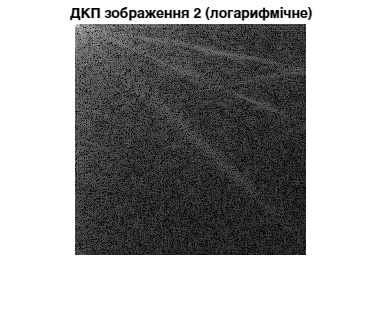

figure, imshow(dct_image2_log, []), title('ДКП зображення 2 (логарифмічне)');

## 4.Відновлення зображення за ДКП-спектром

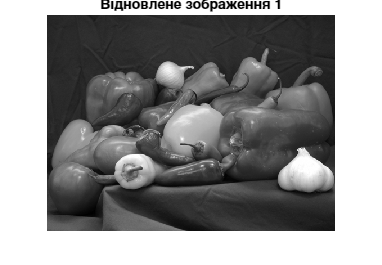

reconstructed_image1 = idct2(dct_image1);
reconstructed_image2 = idct2(dct_image2);

% Виведення результату
figure, imshow(reconstructed_image1, []), title('Відновлене зображення 1');

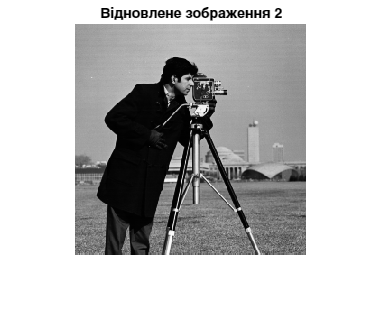

figure, imshow(reconstructed_image2, []), title('Відновлене зображення 2');

## 5.Квантування ДКП-коефіцієнтів для різних значень N

N = 10;  % Крок квантування
dct_image1_quantized = N * round(dct_image1 / N);
dct_image2_quantized = N * round(dct_image2 / N);

**Пояснення:**

- **Як працює квантування?**Квантування працює за принципом округлення значень ДКП до найближчого значення, кратного ***N***. Таким чином, ми зменшуємо кількість можливих значень, що дозволяє зменшити обсяг даних.

- **Результат квантування:**Квантування зменшує точність ДКП-коефіцієнтів, що спричиняє втрату частини інформації, але це дозволяє зменшити розмір файлу при збереженні основних характеристик зображення.

## 6.Відображення результату в логарифмічному масштабі

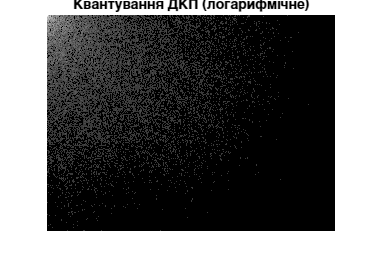

dct_image1_quantized_log = log(abs(dct_image1_quantized) + 1);
dct_image2_quantized_log = log(abs(dct_image2_quantized) + 1);

figure, imshow(dct_image1_quantized_log, []), title('Квантування ДКП (логарифмічне)');

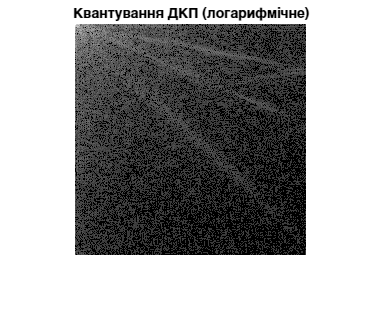

figure, imshow(dct_image2_quantized_log, []), title('Квантування ДКП (логарифмічне)');

**Пояснення:**

- Логарифмічне масштабування дозволяє підкреслити низькочастотні компоненти в спектрі, що зазвичай мають більші амплітуди. Завдяки цьому, зображення ДКП-коефіцієнтів стає більш наочним для аналізу.

- Після квантування на зображенні можна помітити, що дрібні деталі (які мають малі коефіцієнти) втрачаються або стають менш вираженими, оскільки квантування знижує точність цих значень.

## 7.Відновлення зображення після квантування

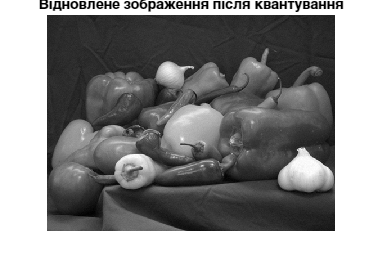

reconstructed_image1_quantized = idct2(dct_image1_quantized);
reconstructed_image2_quantized = idct2(dct_image2_quantized);

% Виведення результату
figure, imshow(reconstructed_image1_quantized, []), title('Відновлене зображення після квантування');

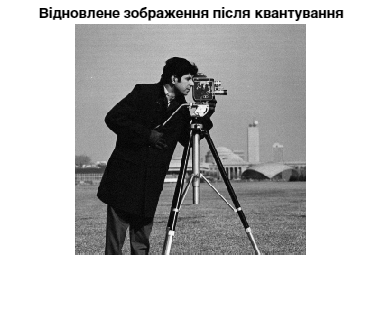

figure, imshow(reconstructed_image2_quantized, []), title('Відновлене зображення після квантування');

**Пояснення:**

- Після квантування коефіцієнтів ДКП зображення можна відновити, застосувавши зворотне ДКП за допомогою функції **idct2**.

- Відновлене зображення буде містити менше деталей через втрату інформації на етапі квантування, тому зображення буде менш чітким. Чим більше крок квантування NNN, тим більша втрата якості.

## **8.Пояснення мети квантування коефіцієнтів ДКП**

**Мета квантування:**Квантування коефіцієнтів ДКП призводить до втрати деякої частини інформації, що дозволяє зменшити обсяг даних для стиснення зображень. Квантування зменшує точність значень коефіцієнтів, що знижує загальний обсяг даних при збереженні значущої частини інформації для відновлення зображення.

## 9.Квантування вихідного зображення

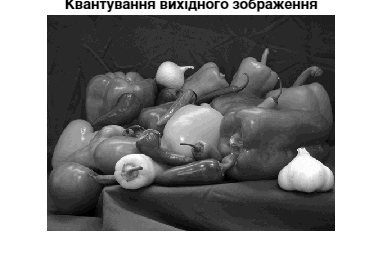

N = 10; % Крок квантування
image1_quantized = round(image1_gray / N) * N;
image2_quantized = round(image2 / N) * N;

% Виведення результату
figure, imshow(image1_quantized, []), title('Квантування вихідного зображення');

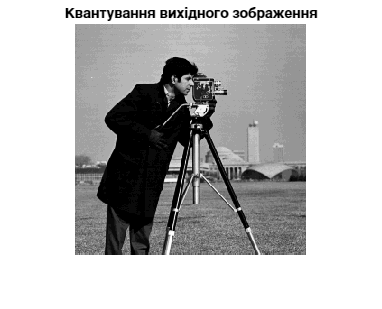

figure, imshow(image2_quantized, []), title('Квантування вихідного зображення');

**Пояснення:**

- У цьому етапі ми застосовуємо квантування до самого зображення, а не до його ДКП. За допомогою цієї процедури, кожен піксель зображення округляється до найближчого значення, кратного **N**.

- **Різниця з квантуванням ДКП:**Квантування зображення безпосередньо призводить до зменшення різниці між пікселями, що може бути більш помітним для дрібних деталей. Водночас, квантування ДКП дозволяє зберегти більше структурних характеристик, зменшуючи помітну втрату якості.

## **10.Недоліки стиснення зображень за допомогою ДКП та квантування коефіцієнтів**

**Недоліки:**

- **Втрата якості:** Квантування знижує точність зображення, що може призвести до втрати деталей, особливо при високих рівнях стиснення.

- **Ручне налаштування параметрів:** Вибір оптимального кроку квантування може бути складним і залежить від конкретного зображення.

- **Залежність від шумів:** Зображення з великим рівнем шуму можуть погіршитися після стиснення через сильне квантування.